# Stock Data - Simulating Returns

In this exercise, you will simulate 100 different paths for the future prices of Magnum Hunter Resources Corporation (MHR) stock, assuming that the MHR returns are taken from one of four different distributions.

## 1.

Run the script `stockDataDistributionFitting.mlx`from the exercise *Stock Data – Distribution Fitting*. This script creates four distributions that are stored in the cell array `retFits`.

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


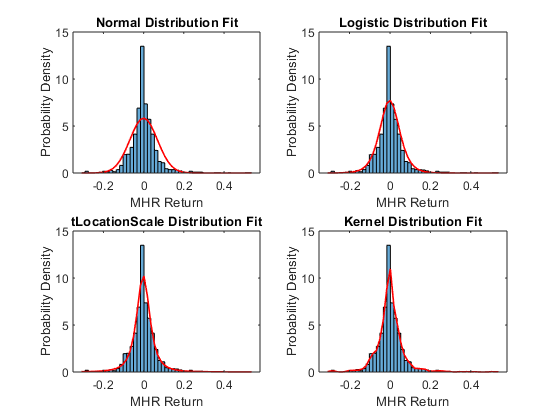

stockDataDistributionFitting

## 2.

For each distribution, use the `random`function togenerate a 252-by-100 matrix of random numbers representing simulated returns for 100 paths over 252 days. Store each matrix into a separate cell of a cell array called `simReturns`.

numOfDays  = 252;
numOfPaths = 100;
simReturns = cell(4,1);

for k = 1:length(retFits)
    simReturns{k} = random(retFits{k},numOfDays,numOfPaths);
end

## 3.

Convert the simulated returns in each cell of `simReturns`into prices using the following:

`simPrices``= ``startPrice``*``exp``(``cumsum``(``simReturns``))`

Use the final price of MHR stock as the `startPrice`, and make sure to add the starting price to the beginning of each path in the simulated prices matrix.  

startPrice = MHR(end);
simPrices = cell(4,1);

for k = 1:length(simReturns)
    simPrices{k} = [ones(1,numOfPaths)*startPrice; startPrice*exp(cumsum(simReturns{k}))];
end

## 4.

Create a `datetime`vector of future dates by adding a vector of 0 to 252 days onto the final date in the `stockPrices `table.

futureDates = stockPrices.Date(end) + days(0:numOfDays)

futureDates = 1×253 datetime array
Columns 1 through 5
   02-May-2011   03-May-2011   04-May-2011   05-May-2011   06-May-2011
Columns 6 through 10
   07-May-2011   08-May-2011   09-May-2011   10-May-2011   11-May-2011
Columns 11 through 15
   12-May-2011   13-May-2011   14-May-2011   15-May-2011   16-May-2011
Columns 16 through 20
   17-May-2011   18-May-2011   19-May-2011   20-May-2011   21-May-2011
Columns 21 through 25
   22-May-2011   23-May-2011   24-May-2011   25-May-2011   26-May-2011
Columns 26 through 30
   27-May-2011   28-May-2011   29-May-2011   30-May-2011   31-May-2011
Columns 31 through 35
   01-Jun-2011   02-Jun-2011   03-Jun-2011   04-Jun-2011   05-Jun-2011
Columns 36 through 40
   06-Jun-2011   07-Jun-2011   08-Jun-2011   09-Jun-2011   10-Jun-2011
Columns 41 through 45
   11-Jun-2011   12-Jun-2011   13-Jun-2011   14-Jun-2011   15-Jun-2011
Columns 46 through 50
   16-Jun-2011   17-Jun-2011   18-Jun-2011   19-Jun-2011   20-Jun-2011
Columns 51 through 55
   21-Jun-2011  

## 5.

For each distribution, visualize the final 252 values of MHR stock prices over time, and add plots for each of the 100 simulated paths found in `simPrices`. Use a separate subplot for each distribution.

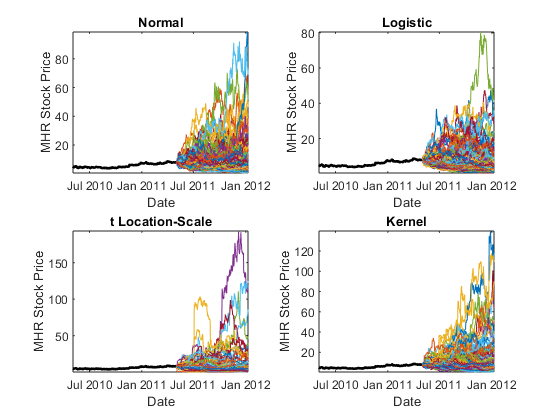

for k=1:length(simPrices)
    subplot(2,2,k)
    plot(stockPrices.Date(end-251:end), MHR(end-251:end), 'k', 'LineWidth',2)
    hold on
    plot(futureDates, simPrices{k})
    xlabel('Date')
    ylabel('MHR Stock Price')
    title(retFits{k}.DistributionName)
    axis tight
end